# MPC using Black-box Models: Innovation Bias Approach 

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India   

## Introduction

   Observer based MPC formulations developed in Module 7 used a discrete linear perturbation model developed from a nonlinear mechanistic model of the plant. In Module 8, we have developed black box state space models starting from input-output data. In this chapter, we illustrate how MPC formulations developed in [Module 7](matlab:open('../7. Model_Predictive_Control_Feedback/L02_InnovationBias_MPC.mlx')) can be modified to work with black-box state space model. 

## State Space MPC with Black-box Observer

   Let us assume that the system/plant may evolve as 

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_d \;d\left(k\right)\\
y\left(k\right)=C\;x\left(k\right)\;+v\left(k\right)
\end{array}$  ------(1) 

where $\left\lbrace d\left(k\right):k=0,1,2\ldotp \ldotp \ldotp \right\rbrace$ represents some unknown/unmeasured disturbance input influencing the system dynamics and $\left\lbrace v\left(k\right):k=0,1,2\ldotp \ldotp \ldotp \right\rbrace$ represents some unknown disturbance in the measured output.

### Internal Model  

We develop MPC using an innovation form of black-box state space model 

  $\begin{array}{l}
\chi \left(k+1\right)=\tilde{\Phi} \chi \left(k\right)+\tilde{\Gamma} u\left(k\right)+\tilde{L} \;e\left(k\right)\\
y\left(k\right)=\tilde{C} \;\chi \left(k\right)+e\left(k\right)
\end{array}$  ------(2)

and use $\hat{x} \left(k\right)$ estimated as 

$\begin{array}{l}
\chi \left(k\right)=\tilde{\Phi} \chi \left(k-1\right)+\tilde{\Gamma} u\left(k-1\right)+\tilde{L} \;e\left(k-1\right)\\
e\left(k-1\right)=y\left(k\right)-\tilde{C} \;\chi \left(k\right)
\end{array}$ ------(3)

for initializing the model predictions. The innovation signal, $y\left(k\right)-\tilde{C} \;\chi \left(k\right)$ computed using (3) contains the information about the unmeasured disturbances and model plant mismatch (MPM).  Now, given a guess of future manipulated inputs 

${\mathrm{U}}_p \left(k\right)=\left\lbrace u\left(k|k\right),u\left(k+1|k\right),\ldotp \ldotp \ldotp ,u\left(k+p-1|k\right)\right\rbrace$ -----(4)

 the internal model (2) and (3) can be used recursively over the prediction horizon 

  $\begin{array}{l}
z\left(k+j+1\right)=\tilde{\Phi} z\left(k+j\right)+\tilde{\Gamma} u\left(k+j|k\right)+\tilde{\mathrm{L}} e\left(k+j\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp ,p-1\;\;\textrm{and}\;\;\;z\left(k\right)=\chi \left(k\right)
\end{array}$  ------(5)


$$\hat{y} \left(k+j\right)=\tilde{\mathrm{C}} z\left(k+j\right)+e\left(k+j\right)\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p\;\;$$
   

Since the future measurements are not available, we need to introduce a simplifying assumption regarding the future innovations, $e\left(k+j\right)$,  while carrying out predictions. It is assumed that the future innovations remain constant at the current values $e\left(k\right)$, i.e. 

$e\left(k+j+1\right)=e\left(k+j\right)\;\;$  ------(6)

Under this assumption, the prediction model reduces to 

 $\begin{array}{l}
z\left(k+j+1\right)=\tilde{\Phi} z\left(k+j\right)+\tilde{\Gamma} u\left(k+j|k\right)+\tilde{\mathrm{L}} e\left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp ,p-1\;\;\textrm{and}\;\;\;z\left(k\right)=\chi \left(k\right)
\end{array}$  ------(7)


$$\hat{y} \left(k+j\right)=\tilde{\mathrm{C}} z\left(k+j\right)+e\left(k\right)\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p\;\;$$


As observed from the simulation exercise at the end of the last lesson, the high frequency component in $e\left(k\right)$ can lead to undue oscillations in the input moves. The low frequency drifting mean of $\left\lbrace e\left(k\right)\right\rbrace$can be estimated using a ***robustness filter ***of the form

$\begin{array}{l}
e_f \left(k\right)=\Phi_e e_f \left(k-1\right)+\left(I-\Phi_e \right)e\left(k\right)\\
\Phi_e =\textrm{diag}\left\lbrack \begin{array}{cccc}
\alpha_1  & \alpha_2  & \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp  & \alpha_1 
\end{array}\right\rbrack 
\end{array}$  ------(8)

 where  $0\le \alpha_i \le 1\;\;\;\;\;i=1,2\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp r$ are the tuning parameters. Using this filtered signal, the assumption about the future innovations is changed as follows  

$e\left(k+j\right)=e_f \left(k\right)\;\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p$  ------(9)

and $e_f \left(k\right)$ is used in prediction of $z\left(k+1\right)$, i.e. 

$z\left(k+1\right)=\tilde{\Phi} \chi \left(k\right)+\tilde{\Gamma} u\left(k|k\right)+\tilde{\mathrm{L}} e_f \left(k\right)$ -----(10)

Thus, the prediction model can be changed to

$\begin{array}{l}
z\left(k+j+1\right)=\tilde{\Phi} z\left(k+j\right)+\tilde{\Gamma} u\left(k+j|k\right)+\tilde{\mathrm{L}} e_f \left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp ,p-1\;\;\textrm{and}\;\;\;z\left(k\right)=\chi \left(k\right)
\end{array}$  ------(11)

$\hat{y} \left(k+j\right)=\tilde{\mathrm{C}} z\left(k+j\right)+e_f \left(k\right)\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p\;\;$ ------(12)

Now, to be consistent with the prediction model, the target state and input calculations need to be modified as follows : when $l=m$, we can derive expression for $u_s \left(k\right)$ as follows 

${\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;u}_s \left(k\right)={\left(G\right)}^{-1} \;\left(r_f \left(k\right)-G_e \;e_f \left(k\right)\right)$----(13)

 $\textrm{where}\;G=\left(\tilde{C} {\left(I-\tilde{\Phi} \right)}^{-1} \tilde{\Gamma} \right)\;\;\;\;\textrm{and}\;\;\;G_e =\left(I+\tilde{C} {\left(I-\tilde{\Phi} \right)}^{-1} \tilde{L} \right)$   ------(14)

When $u_s \left(k\right)$ computed using (13) is outside the input bounds, or when $l\not= m$, the target state can be computed by solving $u_s \left(k\right)$ can be found by solving the following optimization problem

$\min_{u_s \left(k\right)} \left\lbrace {\left(r_f \left(k\right)-y_s \left(k\right)\right)}^T \;W_{\textrm{ys}} \left(r_f \left(k\right)-y_s \left(k\right)\right)\right\rbrace$   ------(15)

subject to,

$y_s \left(k\right)=G\;u_s \left(k\right)+G_e \;e_f \left(k\right)$ ------(16) 

$u^L \le u_s \left(k\right)\le u^H$ ------ (17)

After solving the optimization problem, $x_s \left(k\right)$ can be found using 

$\chi_s \left(k\right)={\left(I-\tilde{\Phi} \right)}^{-1} \left(\tilde{\Gamma} u_s \left(k\right)+\tilde{L} {\mathrm{e}}_f \left(k\right)\right)$ ------(18)

Now, using the prediction model, we present two MPC formulations: (a) State Space MPC and (b) Output Tracking MPC. These are two distinct forms and cannot be converted from one to another by simple variable transformations. 

###  State Space MPC

This is modification of the vanilla MPC formulations introduced in Module 3 and 5.  


$$\;$$
  
$${\mathrm{U}}_p^* \left(k\right)=\overset{\arg \;\min }{{\mathrm{U}}_p \left(k\right)} \;\;J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack$$
   

$J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|z\left(k+p\right)-x_s \left(k\right)\right\|}^2 }_{W_{\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|z\left(k+j\right)-x_s \left(k\right)\right\|}^2 }_{W_x } +{{\left\|u\left(k+j|k\right)-u_s \left(k\right)\right\|}^2 }_{W_u } \right\rbrace$ -----(19)

Subject To

$\begin{array}{l}
z\left(k+j+1\right)=\tilde{\Phi} z\left(k+j\right)+\tilde{\Gamma} u\left(k+j|k\right)+\tilde{\mathrm{L}} e_f \left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp ,p-1\;\;\textrm{and}\;\;\;z\left(k\right)=\chi \left(k\right)
\end{array}$  ------(20)

     $u_L \le u\left(k+j|k\right)\le u_H$   for$j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1$   ------(21) 

To keep the treatment simple, we have only retained input bound constraints. However, other constraints such as, input rate constraints or output bounds can be introduced in the formulation. Further, the cost function can be modified by including input rate penalty terms. Note that the state weighting matrix is chosen as$W_x =C^T W_y C$  where $W_y$ is +ve definite output tracking error weighting matrix. 

### Transformation of State Space MPC to QP Problem 

Conversion of the MPC formulation to QP is carried out as discussed in Lesson 2 of Module 7. The main differences are 

- Prediction Model 

$\begin{array}{l}
z\left(k+j\right)={\tilde{\Phi} }^j \chi \left(k\right)+{\tilde{\Phi} }^{j-1} \tilde{\Gamma} u\left(k|k\right)+{\tilde{\Phi} }^{j-2} \tilde{\Gamma} u\left(k+1|k\right)+\ldotp \ldotp \ldotp \ldotp \ldotp +\tilde{\Gamma} u\left(k+j-1|k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left({\tilde{\Phi} }^{j-1} +{\tilde{\Phi} }^{j-2} +\ldotp \ldotp \ldotp \ldotp \ldotp +I\right)\;\tilde{L} \;e_f \left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p\;\;
\end{array}$   -----(22)

-  Matrices $\left(S_x ,S_u ,S_e \;\right)$ in the QP formulation are computed using $\left(\tilde{\Phi} ,\;\tilde{\Gamma} ,\;\tilde{C} \right)$

- QP problem changes to 

$J\;=\frac{1}{2}{{\;U}_f \left(k\right)}^T \;\mathbf{H}\;U_f \left(k\right)+{F\left(k\right)}^T U_f \left(k\right)$  -----(23a) 

$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathbf{H}=2\left({S_u }^T {\mathbf{W}}_X S_u +{\mathbf{W}}_U \right)\;\\
\mathrm{and}\;\;F\left(k\right)=2\left({\left(S_u \right)}^T {\mathbf{W}}_X \right)\;\left(S_x \chi \left(k\right)+S_e \;e_f \left(k\right)-{\mathbf{I}}_{X\;\;} \chi_s \left(k\right)\right)-2\;\left({\mathbf{W}}_U {\mathbf{I}}_U \right)u_s \left(k\right)
\end{array}$ ------(23b)

- Target state computations are carried out using $\left(\tilde{\Phi} ,\;\tilde{\Gamma} ,\;\tilde{C} \right)$

#### Steps in Online Implementation of QP-MPC  

 Let us summarize the steps involved in the modified MPC formulation at a k'th sampling instant 

- Step 1: Acquire measurement $y\left(k\right)$ from the plant and find the mismatch signal, $e\left(k\right)=y\left(k\right)-\tilde{C} \;\chi \left(k\right)$, using equation (3) 

- Step 2: Compute filtered model plant mismatch signal, $e_f \left(k\right)$, using equation (8)

- Step 3: Compute filtered setpoint $r_f \left(k\right)$

- Step 4: Compute target states and inputs ($\left.x_s \left(k\right),u_s \left(k\right)\right)$ using either equation (13)-(14) or by solving optimization problem (15) to (17)

- Step 5: Solve the constrained optimization problem (QP formulation of MPC) set on the moving horizon framework and compute optimal input $\left\lbrace u^* \left(k+j|k\right):j=0,1,2,\ldotp \ldotp \ldotp ,p-1\right\rbrace$

- Step 6: Set $u\left(k\right)=u^* \left(k|k\right)$, update the internal model states using equation (2) and find $\chi \left(k+1\right)$

- Step 7: Communicate $u\left(k\right)$ to the plant 

### Quadruple Tank Process Simulation

To demonstrate efficacy of identified state space model, we demonstrate control of Q-Tank process using an identified state space model with matrices. To design the controller, we set $W_x =$${\tilde{\left(C\right)} }^T W_y \tilde{C}$ and derive a QP formulation that solves the output tracking MPC formulation. 

 
clear all 
close all

global QTank U_k D_k

Set_Graphics_Parameters ;   % This script file sets font size and line thickness for figures 

**Task 1:** Select operating point: **(1) Minimum Phase Operation (2) Non-minimum phase operation. **This will load the parameters specific to the operating point. Let us set the operating point to Minimum Phase first

operating_pt=2; 
if operating_pt==1
load QTank_MinPhase_Model
else
    load QTank_NonMinPhase_Model
end

**Initialize linear model for plant simulation **

phy= QTank.phy  

phy =     0.9404         0    0.0901         0
         0    0.9600         0    0.0606
         0         0    0.9070         0
         0         0         0    0.9381


gam = QTank.gama_u 

gam =     0.1871    0.0144
    0.0069    0.1370
         0    0.2955
    0.2167         0


gam_d = QTank.gama_d 

gam_d =     0.0026
    0.0023
    0.0544
    0.0727


C_mat = QTank.C_mat  % Levels h(1) and h(2) are measured in quadruple tank 

C_mat =     0.5000         0         0         0
         0    0.5000         0         0


[n_op, nx ] = size(C_mat)  ;
[n_st, n_ip] = size(gam) ;
[nx, n_d] = size(gam_d) ;

**Initialize internal model for MPC **

**Task 2: **Initialize internal model for MPC to the black box state space model or grey box identified model from input-output data, which we have created in module 8. 

model_type=2 

model_type = 2

Then the function** Load_BlackBox_Model (operating_pt, model_type) **loads the model and initializes matrices for mpc formulation.

mpc=Load_BlackBox_Model(operating_pt, model_type)

mpc = struct with fields:
      phy: [4×4 double]
      gam: [4×2 double]
    C_mat: [2×4 double]
     n_st: 4
     n_op: 2
     n_ip: 2
    L_mat: [4×2 double]


mpc.phy 

ans =     0.9398         0   -0.2539         0
         0    0.9596         0    0.1145
         0         0    0.9049         0
         0         0         0    0.9391


mpc.gam

ans =     0.1863    0.0011
    0.0073    0.1340
         0   -0.1104
    0.1133         0


mpc.C_mat

ans =     0.5000         0         0         0
         0    0.5000         0         0


mpc.L_mat

ans =    -0.0037   -0.0018
    0.0032   -0.0040
    0.0069    0.0051
    0.0323    0.0134


Q_mat = QTank.Q_mat ;
R_mat = QTank.R_mat ;

**Task 3**: Set the simulation run time N = 750 to study only the disturbance rejection and N = 1000 to additionally see servo response. 

N = 1000 ;      % Simulation run time

**MPC Tuning Parameters**

**Task 4: **Set the prediction horizon n_pred to interval >= 50**. **Set it to 50 first.

mpc.n_pred =50; 

**Task 5:** We have created variables ${\textrm{mpc}\ldotp W}_y$, the **Output Weighting Matrix  **and ${\textrm{mpc}\ldotp W}_u$, the **Input Weighting Matrix**.  [One can use eye command in MATLAB](https://in.mathworks.com/help/matlab/ref/eye.html) or form the matrices as shown below.

$W_y =\left\lbrack \begin{array}{cc}
\alpha_1  & 0\\
0 & \alpha_2 
\end{array}\right\rbrack$,  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$

Here $\alpha$ and $\beta$  1 and 10 respectively. These have to be tuned to achieve the desired performance. We can change them and observe the effect on outputs

beta(1)=1;
beta(2)=1;
disp('Input weighting matrix')
mpc.Wu= diag(beta) ;  % Input weighting matrix
alpha(1)=10;
alpha(2)=10;
disp('Output weighting matrix')
mpc.Wy=diag(alpha);  % State weighting matrix

mpc.u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
mpc.u_L = [0 0]' - QTank.Us ;  
mpc.deluL = [] ; mpc.deluH = [] ; 
mpc.xs_k = zeros(mpc.n_st,N);
mpc.us_k = zeros(n_ip,N) ;
mpc.xkhat = zeros(mpc.n_st,N);
mpc.yhatk = zeros(n_op,N) ;

 **Task 6**: To understand the advantages of using a closed loop state estimator, set **CL_Observer_ON** flag to **No** so that MPC controller reduces to vanilla MPC based on the model as open loop observer. 

CL_Observer_ON=1;% Set this value to zero to simulate open loop observer based vanilla MPC 
 mpc.L_mat =  CL_Observer_ON * mpc.L_mat ;   % Use observer gain of the innovation form of the state space model 

** Generate QP matrices for MPC**

[mpc] = Gen_QP_Matrices_Tracking_Estimator(mpc) ;

**Task 7: **Change disturbance filter parameter between 0.9 and 0.99. Setting it equal to zero will eliminate innovation filter. 

alfa_e=0.94;
mpc.phy_d = alfa_e * eye(n_op) ;   % Disturbance filter matrix 
mpc.dkhat= zeros(n_op,N); % Model plant mismatch signal 
mpc.dkhat_f = zeros(n_op,N); % Filtered Model plant mismatch signal 

**Task 8: **Change setpoint filter parameter between 0.9 and 0.99. Setting it equal to zero will eliminate innovation filter. 

rk_f = zeros(n_op,N);  
beta_r=0.9;
phy_r = beta_r * eye(n_op) ; % Setpoint filter matrix 

**Process simulation related matrices are initialized here. **

N = 1000 ;      % Simulation run time
% Matrices for simulating system dynamics 
xk = zeros(n_st,N);
xk(:,1) = [-1 1 -1 1]';   % Initial state is away from the origin
uk = zeros(n_ip,N) ;
yk = zeros(n_op,N);
yk(:,1) = C_mat * xk(:,1) ; 
dk = zeros(1,N) ;
rk = [0 0]';

**Task 9:** Set the value of Noise_ON to 1 to introduce white noise disturbances in the states and measurements.

Noise_ON=1% Set this value to 1 to introduce white noise disturbances  

Noise_ON = 1

% Generate state and measurement noise sequences 
wk = mvnrnd(zeros(n_d,1), Q_mat, N) ;
wk = Noise_ON * wk' ;
vk = mvnrnd(zeros(n_op,1), R_mat, N) ;
vk = Noise_ON * vk' ;

% Disturbance input 
for k = 1:N
    if ( k < 250 )
        dk(k) = 0 ;
    elseif (k >= 250 ) && (k < 500)
        dk(k) = 0.5 ;  % Introduce disturbance change at k = 250
    else
        dk(k) = 0.25 ;  % Introduce another disturbance change at k = 500
    end
end
dk = dk + [zeros(1, 250) wk(251:end) ] ;

**Closed loop simulation with MPC QP **

**Task 10: **Select Plant_Sim as Linear for simulating Q Tank process using linear discrete model.

Plant_Sim =0  ;

for k = 1:N-1
    % Controller calculations at instant k assuming state vector is perfectly measured
    kT(k) = (k-1) ;

    if ( k > 750 ), rk = [1.5 -1.5]';  end   % Introduce setpoint change at 750
    rk_f(:,k+1) = phy_r * rk_f(:,k) + (eye(n_op) - phy_r) * rk   ;

    % MPC implementation at instant k

    [mpc, u_k ] = MPCQP_StateSpace( mpc, yk(:,k), rk_f(:,k+1), k ) ;
    mpc.uk = u_k ;

    % Quadruple tank Plant Simulation from k to k+1

    if (Plant_Sim )
        uk(:,k) = mpc.uk ;
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
    else
        uk(:,k) = mpc.uk ;
        U_k = QTank.Us + mpc.uk ;
        D_k =  QTank.Ds + dk(k)  ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
    yk(:,k+1) = C_mat * xk(:,k+1) + vk(:,k+1);  %Measurement with noise

end
% Setting last vectors for plotting purpose 
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;
mpc.dkhat(:,N) = mpc.dkhat(:,N-1) ; 
mpc.us_k(:,N) = mpc.us_k(:,N-1) ;
mpc.xs_k(:,N) = mpc.xs_k(:,N-1) ;

**Display Simulation Results **

Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  Rk_f = rk_f + C_mat * QTank.Xs ;
u_limit = [mpc.u_L(1)*ones(N,1) mpc.u_H(1)*ones(N,1)]  ;


** Controlled output profiles **

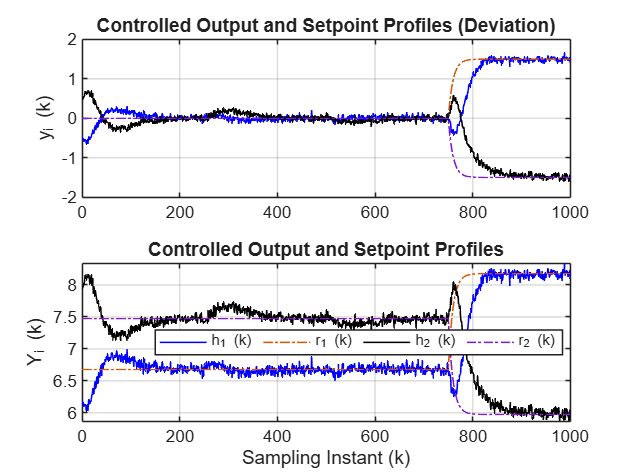

figure, subplot(211), 
plot(kT, yk(1,:), 'b',  kT, rk_f(1,:), '-.', kT, yk(2,:), 'k', kT, rk_f(2,:), '-.'), grid
title('Controlled Output and Setpoint Profiles (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Rk_f(1,:), '-.', kT, Yk(2,:), 'k', kT, Rk_f(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')
legend('h_1 (k)', 'r_1 (k)', 'h_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best')
title('Controlled Output and Setpoint Profiles')

**Manipulated input profiles**

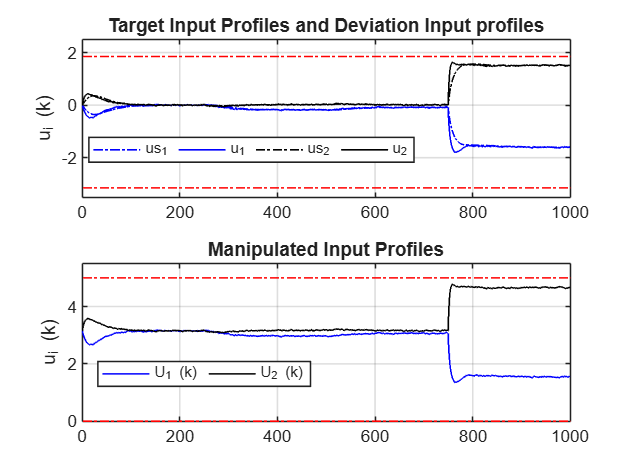

figure, subplot(211), stairs(kT, mpc.us_k(1,:)', '-.b','LineWidth',1), grid
hold on
stairs(kT, uk(1,:)', 'b','LineWidth',1)
stairs(kT, mpc.us_k(2,:)', '-.k','LineWidth',1)
stairs(kT, uk(2,:)', 'k','LineWidth',1)
stairs(u_limit, '-.r', 'LineWidth',1)
axis([0 N -3.5 2.5])
hold off
ylabel('u_i (k)'), title('Target Input Profiles and Deviation Input profiles')
legend( 'us_1', 'u_1', 'us_2', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs(kT, Uk(1,:)', 'b','LineWidth',1),  grid
hold on, stairs(kT, Uk(2,:)', 'k','LineWidth',1),
stairs(u_limit+QTank.Us', '-.r', 'LineWidth',1), hold off
axis([0 N 0 5.5]), ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

** Disturbance input and Model Plant Mismatch profiles**

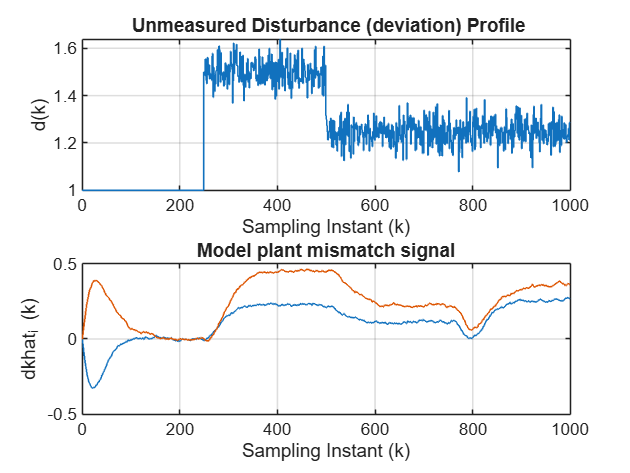

figure, subplot(211), stairs( kT, Dk,'LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)')
title(' Unmeasured Disturbance (deviation) Profile')
subplot(212), stairs( kT, mpc.dkhat_f','LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('dkhat_i (k)')
title('Model plant mismatch signal')

**System State profiles and MPC internal model profiles  **

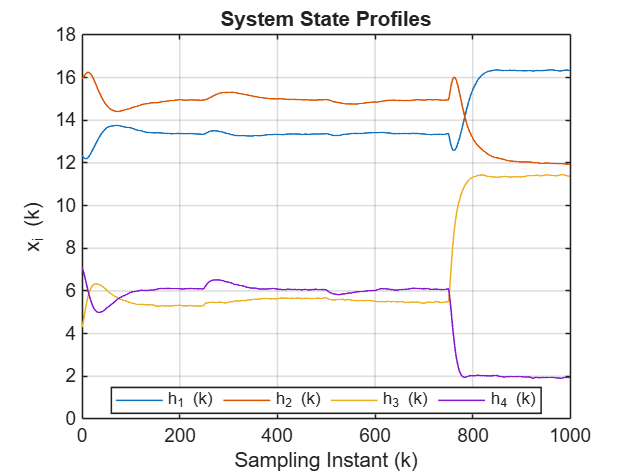

figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('h_1 (k)', 'h_2 (k)', 'h_3 (k)', 'h_4 (k)', 'Orientation','horizontal','Location','Best')
title('System State Profiles')

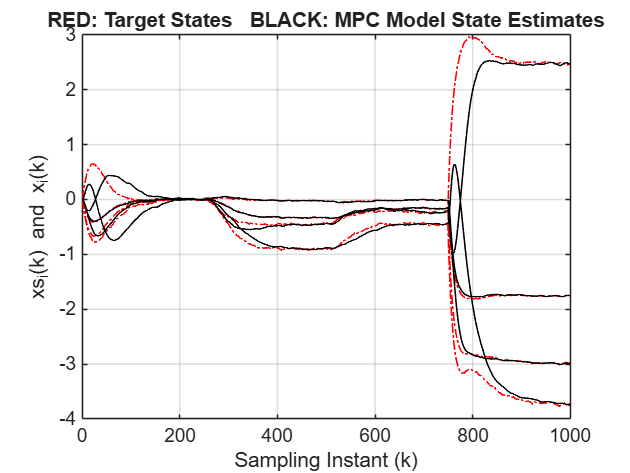

figure, plot(kT, mpc.xs_k, '-.r', kT, mpc.xkhat, 'k'), grid
title('RED: Target States   BLACK: MPC Model State Estimates')
xlabel('Sampling Instant (k)'), ylabel('xs_i(k) and x_i(k)')

Observe the results of simulation. The controlled outputs are tracking the desired values. 

**Task 11:**Now change the type of identified model and observe the results. We can see that the controller performs well with all the identified models. 

**Task 12**: Let us change the operating point to Nonminimum phase and observe the results. Does the performance remain same? We may have to retune the controller.

**Task 13: **Try changing the input and output weighting matrices and see the effect.

**Task 14: **Repeat the exercise for nonlinear plant simulation. Now observe the plant model mismatch signal.

## Output Tracking MPC 

This is closer to similar to the initial versions of MPC formulations used in the industrial practice. 


$$\;$$
  
$${\mathrm{U}}_p^* \left(k\right)=\overset{\arg \;\min }{{\mathrm{U}}_p \left(k\right)} \;\;J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack$$
   

$J\left\lbrack y\left(k\right),\hat{x} \left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|\hat{y} \left(k+p\right)-r_f \left(k\right)\right\|}^2 }_{W_{y,\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|\hat{y} \left(k+j\right)-r_f \left(k\right)\right\|}^2 }_{W_y } \;+{{\left\|u\left(k+j|k\right)-u_s \left(k\right)\right\|}^2 }_{W_u } +{{\left\|\Delta u\left(k+j|k\right)\right\|}^2 }_{W_{\Delta u} } \right\rbrace$  ------(24)


$$\begin{array}{l}
\Delta u\left(k+j|k\right)=u\left(k+j|k\right)-\Delta u\left(k+j-1|k\right)\;\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp ,p-1\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Delta u\left(k|k\right)=\Delta u\left(k|k\right)-u\left(k-1\right)
\end{array}$$


Subject To

$\begin{array}{l}
z\left(k+j+1\right)=\tilde{\Phi} z\left(k+j\right)+\tilde{\Gamma} u\left(k+j|k\right)+\tilde{\mathrm{L}} e_f \left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp ,p-1\;\;\textrm{and}\;\;\;z\left(k\right)=\chi \left(k\right)
\end{array}$  ------(25)

$\hat{y} \left(k+j\right)=\textrm{Cz}\left(k+j\right)+e_f \left(k\right)\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p\;\;$  ------(26)

${\Delta u}_L \le \Delta u\left(k+j|k\right)\le {\Delta u}_H \;\textrm{for}\;\;j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1\;$   ------(27)

     $u_L \le u\left(k+j|k\right)\le u_H$   for $j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1$ -----(28) 

Again, to keep the treatment simple, we have only retained input bound constraints. However, other constraints such as, output bounds or those arising from use of control horizon smaller than the prediction horizon, can be introduced in this formulation. Further, the cost function can be modified by including input target penalty terms. The matrix $W_{y,\infty }$ appearing on the R.H.S. of the above equation can be found by solving discrete Lyapunov equation when $\rho \left(\Phi \right)<1$

${\Phi^T W_{y,\infty } \Phi -W}_{y,\infty } ={-C}^T W_y C$ ------(29)

### Transformation of Output Tracking MPC to QP Problem 

Conversion of the MPC formulation to QP is carried out as discussed in Lesson 2 of Module 7. The main differences are 

- Prediction Model 

$\begin{array}{l}
z\left(k+j\right)={\tilde{\Phi} }^j \chi \left(k\right)+{\tilde{\Phi} }^{j-1} \tilde{\Gamma} u\left(k|k\right)+{\tilde{\Phi} }^{j-2} \tilde{\Gamma} u\left(k+1|k\right)+\ldotp \ldotp \ldotp \ldotp \ldotp +\tilde{\Gamma} u\left(k+j-1|k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;+\left({\tilde{\Phi} }^{j-1} +{\tilde{\Phi} }^{j-2} +\ldotp \ldotp \ldotp \ldotp \ldotp +I\right)\;\tilde{L} \;e_f \left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{for}\;j=1,2,\ldotp \ldotp \ldotp \ldotp ,p\;\;
\end{array}$   -----(30)

-  Matrices $\left(S_x ,S_u ,S_e \;\right)$ in the QP formulation are computed using $\left(\tilde{\Phi} ,\;\tilde{\Gamma} ,\;\tilde{C} \right)$

- QP problem changes to 

$J\;=\frac{1}{2}{{\;U}_f \left(k\right)}^T \;\mathbf{H}\;U_f \left(k\right)+{F\left(k\right)}^T U_f \left(k\right)$  -----(31a) 

$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathbf{H}=2\left({S_u }^T {\mathbf{W}}_Y S_u +{\mathbf{W}}_U +\Psi^T {\mathbf{W}}_{\Delta U} \Psi \right)\;\\
F\left(k\right)={2\left(S_u \right)}^T {\mathbf{W}}_Y \;\left(S_x \chi \left(k\right)+S_e \;e_f \left(k\right)-R_f \left(k\right)\right)\;-2\left(\Psi^T \;{\mathbf{W}}_{\Delta U} \Psi_0 \right)u\left(k-1\right)-2\;\left({\mathbf{W}}_U {\mathbf{I}}_U \right)u_s 
\end{array}$  ------(31b)

- Target state computations are carried out using $\left(\tilde{\Phi} ,\;\tilde{\Gamma} ,\;\tilde{C} \right)$

### Quadruple Tank Simulation 

In this section, we repeat the simulation exercise carried out in the previous section using the output tracking MPC. 

**MPC Tuning Parameters**

**Task 1: **Set the prediction horizon n_pred to interval >= 50**. Note: **Control horizon is set equal to prediction horizon 

mpc.n_pred = 50 ;     

**Task 2:** We have created variables ${\textrm{mpc}\ldotp W}_u$, the **Input Weighting Matrix,** ${\textrm{mpc}\ldotp W}_{\textrm{delu}}$, the **Input Rating Weighting Matrix **and . Set them as identity matrices. [One can use eye command in MATLAB](https://in.mathworks.com/help/matlab/ref/eye.html) or form the matrices as shown below.

 $W_u =\alpha \times \left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$,   and  $W_{\Delta u} =\beta \times \left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$, $W_y =\gamma \times \left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$

Let the settings for $\alpha$,$\beta$  and $\gamma$ be at 1, 0  and 10.

These have to be tuned to achieve the desired performance. We can change them and observe the effect on outputs

alpha=1;
disp('Input weighting matrix')

Input weighting matrix


mpc.Wu = alpha* eye(n_ip);
beta=0;
disp('Input Rate weighting matrix')

Input Rate weighting matrix


mpc.Wdelu = beta* eye(n_ip) ;% Input Rate weighting matrix. Note: Effect is seen only if large weighting is used 
gamma=10;
disp('Output weighting matrix')

Output weighting matrix


mpc.Wy = gamma * eye(n_op);  % Output weighting matrix

mpc.u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
mpc.u_L = [0 0]' - QTank.Us ;  
% mpc.deluL = [] ; mpc.deluH = [] ; 
mpc.deluH = [0.025 0.025]';  % Specify input rate constraints.
mpc.deluL = -mpc.deluH ;

mpc.xs_k = zeros(mpc.n_st,N);
mpc.us_k = zeros(n_ip,N) ;
mpc.xkhat = zeros(mpc.n_st,N);
mpc.yhatk = zeros(n_op,N) ;

 **Task 3**: To understand the advantages of using a closed loop state estimator, choose $L=\left\lbrack 0\right\rbrack$ by setting the flag to zero so that MPC controller reduces to vanilla MPC based on the model as open loop observer. 

CL_Observer_ON=1;
 mpc.L_mat =  CL_Observer_ON *mpc.L_mat ;   % Use observer gain of the innovation form of the state space model 

**Generation of  QP matrices**

[ mpc] = Gen_QP_Matrices_OP_Tracking_delU(mpc) ;

**Task 4: **Change disturbance filter parameter between 0.9 and 0.99. Setting it equal to zero will eliminate innovation filter. 

alfa_e=0.98;
mpc.phy_d = alfa_e * eye(n_op) ;   % Disturbance filter matrix 
mpc.dkhat= zeros(n_op,N); % Model plant mismatch signal 
mpc.dkhat_f = zeros(n_op,N); % Filtered Model plant mismatch signal 

**Task 5: **Change setpoint filter parameter between 0.9 and 0.99. Setting it equal to zero will eliminate innovation filter. 

rk_f = zeros(n_op,N); 
beta_r=0.9;
phy_r = beta_r * eye(n_op) ; % Setpoint filter matrix 

**Process simulation related matrices are initialized here. **

N=1000;
% Matrices for simulating system dynamics 
xk = zeros(n_st,N);
xk(:,1) = [-1 1 -1 1]';   % Initial state is away from the origin
uk = zeros(n_ip,N) ;
yk = zeros(n_op,N);
yk(:,1) = C_mat * xk(:,1) ; 
dk = zeros(1,N) ;
rk = [0 0]';
gam_d=QTank.gama_d;

**Task 6:** Set the value of Noise_ON to 1 to introduce white noise disturbances in the states and measurements.

Noise_ON=1% Set this value to 1 to introduce white noise disturbances  

Noise_ON = 1

% Generate state and measurement noise sequences 
wk = mvnrnd(zeros(n_d,1), Q_mat, N) ;
wk = Noise_ON * wk' ;
vk = mvnrnd(zeros(n_op,1), R_mat, N) ;
vk = Noise_ON * vk' ;

% Disturbance input 
for k = 1:N
    if ( k < 250 )
        dk(k) = 0 ;
    elseif (k >= 250 ) && (k < 500)
        dk(k) = 0.5 ;  % Introduce disturbance change at k = 250
    else
        dk(k) = 0.25 ;  % Introduce another disturbance change at k = 500
    end
end
dk = dk + [zeros(1, 250) wk(251:end) ] ; 

**Closed loop simulation with using QP-LMPC**

state_est_err = zeros(n_st,N) ;

**Task 7: **Select Plant_Sim as Linear for simulating Q Tank process using linear discrete model.

Plant_Sim =0  ;

for k = 1:N-1
    % Controller calculations at instant k assuming state vector is perfectly measured 
    kT(k) = (k-1) ;

    if ( k > 750 ), rk = [1.5 -1.5]'; 
    end   % Introduce setpoint change at 750 
    rk_f(:,k+1) = phy_r * rk_f(:,k) + (eye(n_op) - phy_r) * rk   ; 

     % MPC implementation at instant k
    [mpc, u_k ] = MPCQP_OutputTracking( mpc, yk(:,k), rk_f(:,k+1), k ) ;
     mpc.uk = u_k ;
  
    % Quadruple tank Plant Simulation from k to k+1

    if (Plant_Sim )
        uk(:,k) = mpc.uk ;
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
    else
        uk(:,k) = mpc.uk ;
        U_k = QTank.Us + mpc.uk ;
        D_k =  QTank.Ds + dk(k)  ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
    yk(:,k+1) = C_mat * xk(:,k+1) + vk(:,k+1);  %Measurement with noise

 end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;
mpc.dkhat(:,N) =mpc.dkhat(:,N-1) ; 
mpc.us_k(:,N) = mpc.us_k(:,N-1) ;
mpc.xs_k(:,N) = mpc.xs_k(:,N-1) ;

**Display simulation results **

Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  Rk_f = rk_f + C_mat * QTank.Xs ;
u_limit = [mpc.u_L(1)*ones(N,1) mpc.u_H(1)*ones(N,1)]  ;


**Controlled output profiles **

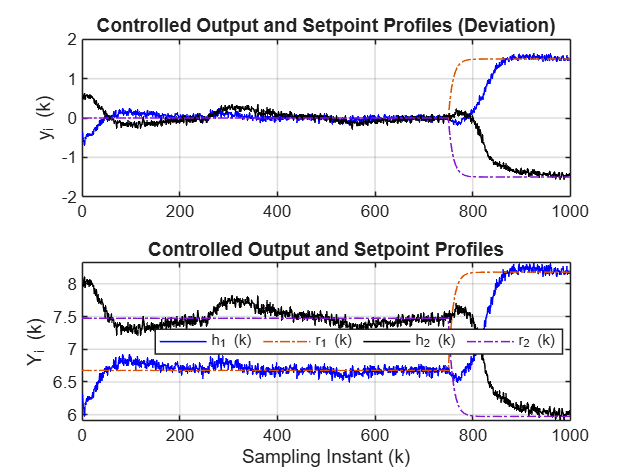

figure, subplot(211), 
plot(kT, yk(1,:), 'b',  kT, rk_f(1,:), '-.', kT, yk(2,:), 'k', kT, rk_f(2,:), '-.'), grid
title('Controlled Output and Setpoint Profiles (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Rk_f(1,:), '-.', kT, Yk(2,:), 'k', kT, Rk_f(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')
legend('h_1 (k)', 'r_1 (k)', 'h_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best')
title('Controlled Output and Setpoint Profiles')

**Manipulated input profiles**

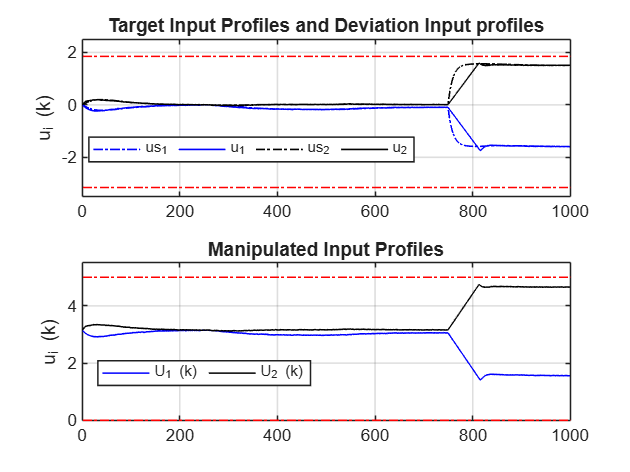

figure, subplot(211), stairs(kT, mpc.us_k(1,:)', '-.b','LineWidth',1), grid
hold on
stairs(kT, uk(1,:)', 'b','LineWidth',1)
stairs(kT, mpc.us_k(2,:)', '-.k','LineWidth',1)
stairs(kT, uk(2,:)', 'k','LineWidth',1)
stairs(u_limit, '-.r', 'LineWidth',1)
axis([0 N -3.5 2.5])
hold off
ylabel('u_i (k)'), title('Target Input Profiles and Deviation Input profiles')
legend( 'us_1', 'u_1', 'us_2', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs(kT, Uk(1,:)', 'b','LineWidth',1),  grid
hold on, stairs(kT, Uk(2,:)', 'k','LineWidth',1),
stairs(u_limit+QTank.Us', '-.r', 'LineWidth',1), hold off
axis([0 N 0 5.5]), ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

**Disturbance input and Model Plant Mismatch profiles **

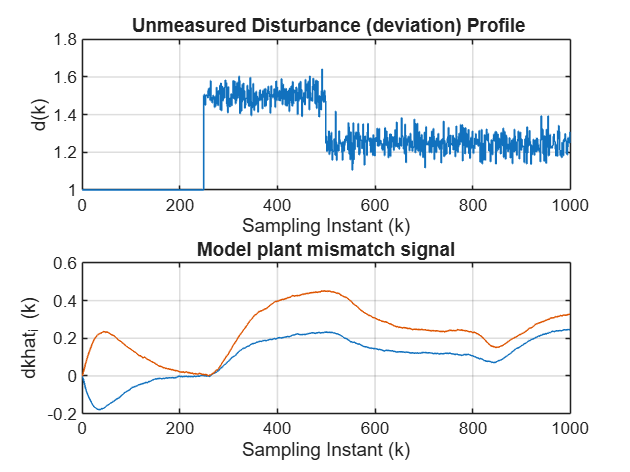

figure, subplot(211), stairs( kT, Dk,'LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)')
title(' Unmeasured Disturbance (deviation) Profile')
subplot(212), stairs( kT, mpc.dkhat_f','LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('dkhat_i (k)')
title('Model plant mismatch signal')

** System State profiles and MPC internal model profiles  **

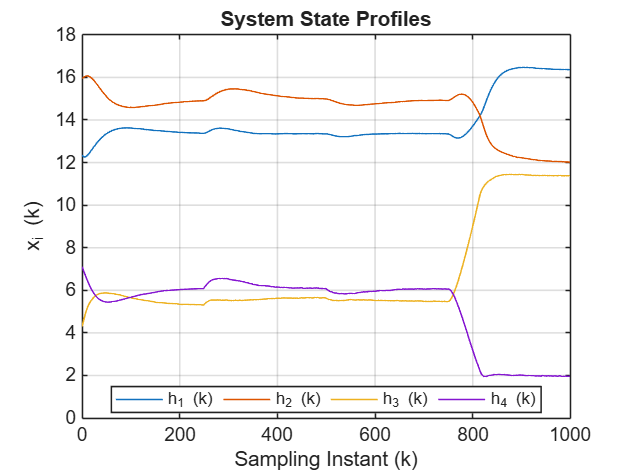

figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('h_1 (k)', 'h_2 (k)', 'h_3 (k)', 'h_4 (k)', 'Orientation','horizontal','Location','Best')
title('System State Profiles')

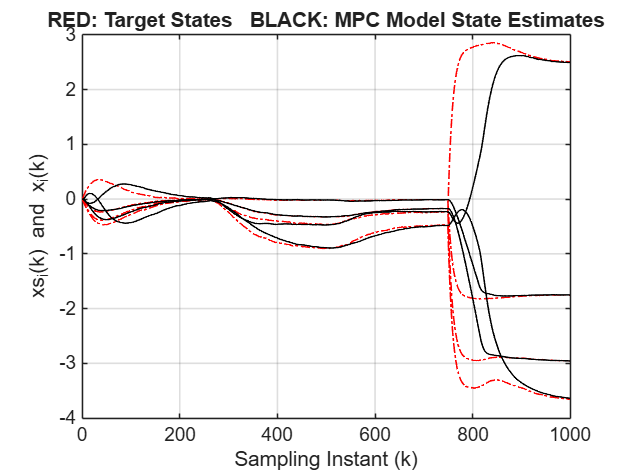

figure, plot(kT, mpc.xs_k, '-.r', kT, mpc.xkhat, 'k'), grid
title('RED: Target States   BLACK: MPC Model State Estimates')
xlabel('Sampling Instant (k)'), ylabel('xs_i(k) and x_i(k)')

Observe the results. We can see that the plant outputs are driven towards the desired set points. The model states of mpc almost follow the target states. 

**Task 8:**Now change the type of identified model and observe the results. We can see that the controller performs well with all the identified models. 

**Task 9**: Let us change the operating point to Nonminimum phase and observe the results. Does the performance remain same? We may have to retune the controller.

**Task 10: **Try changing the input and output weighting matrices and see the effect. Also change the filter parameters

**Task 11: **Repeat the exercise for nonlinear plant simulation.

## Conclusions 

In this lesson, we have modified the state space MPC formulation that used a linearized mechanistic model to an MPC formulation that uses a black-box state space model. Further, using Q-Tank simulations, different features of the State Space MPC have been demonstrated. Analysis of the simulation results reveals that black-box model based MPC gives closed loop performance comparable to mechanistic model based MPC. 